University of Science and Technology in Zewail City

Communication and Information Engineering Program

CIE 247: [Digital Signal Processing - Spring 2026](https://classroom.google.com/u/1/c/ODI1MzU5NDE0MDQ0)

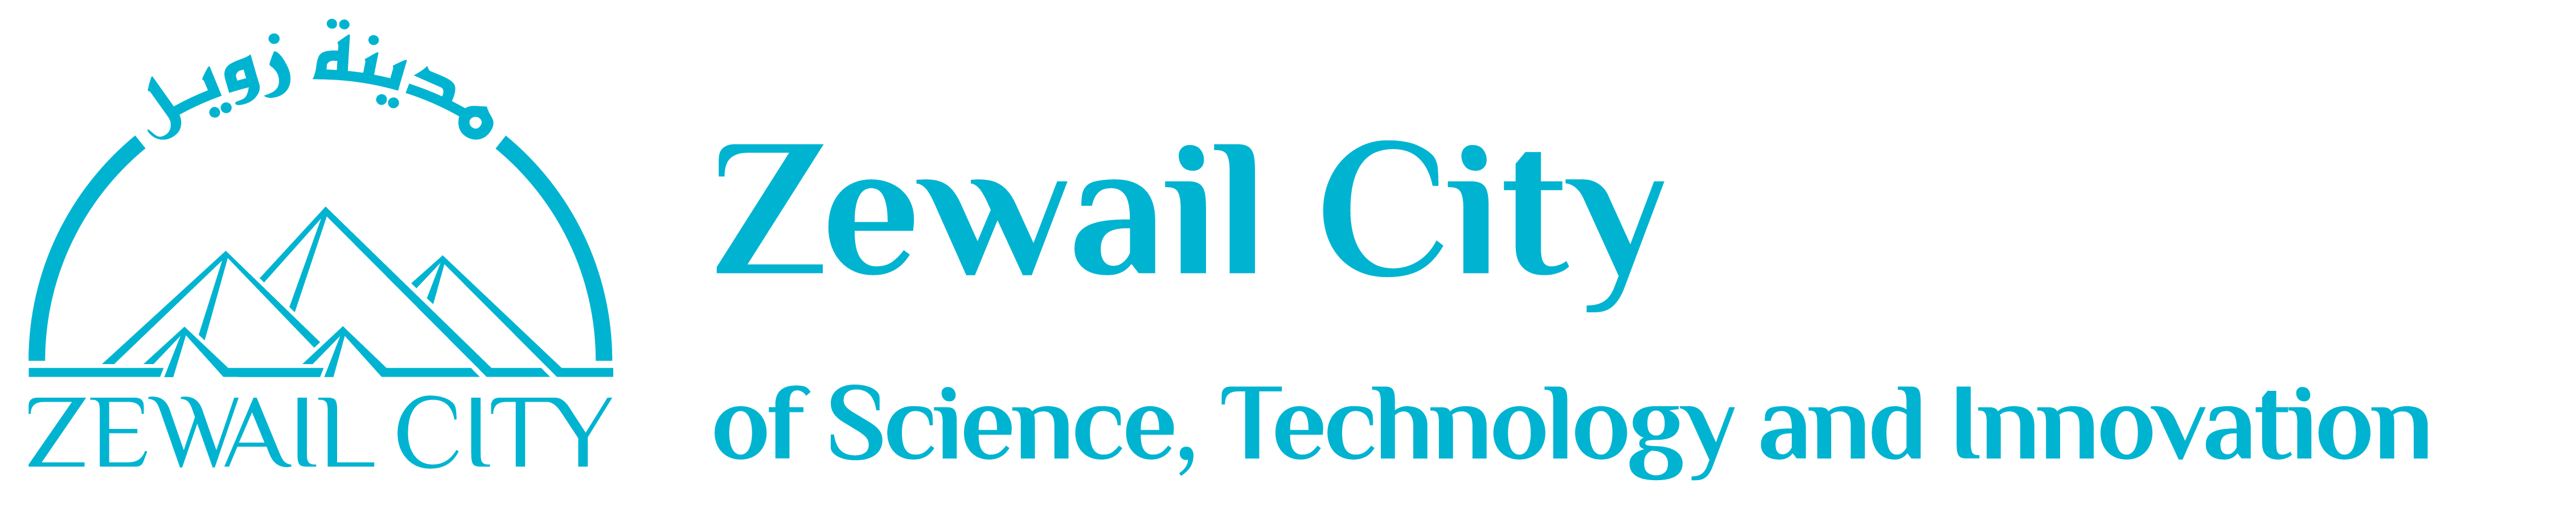

## Project Title: ECG Signal Denoising for Telemedicine Applications

Author: Mohammed Soliman-202402280

Supervision: Prof. Ahmed Eltrass, Eng. Retaj Yousri, Eng. Eman Abdelnaby

clear; close all; clc;

### Loading Function.

function [ecg_segment, time_axis] = load_ecg_segment(record_str, start_sample, duration_s, fs)
    datFile = [record_str, '.dat'];
    fid = fopen(datFile, 'rb');
    data = fread(fid, 'uint8');
    fclose(fid);

    nsamples = floor(length(data) / 3) * 2;
    sig1 = zeros(1, nsamples);
    idx = 1;

    for i = 1:3:length(data)-2
        b1 = data(i); b2 = data(i+1); 
        s1 = bitshift(b1, 2) + bitshift(b2, -6);
        if s1 > 1023, s1 = s1 - 2048; end
        sig1(idx) = s1;
        idx = idx + 1;
    end

    segment_len = duration_s * fs;
    ecg_segment = sig1(start_sample : start_sample + segment_len - 1);
    time_axis = (0:segment_len-1) / fs;
end

### Filters Design and Visualization.

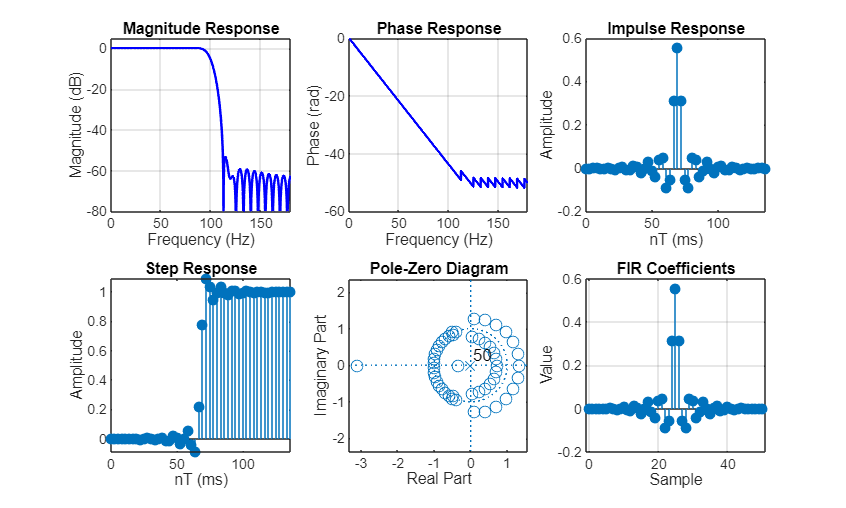

fs = 360;
nyquist = fs/2;

%Filter 1: Low-pass FIR
lp_order = 50; 
lp_fpass = 100;
lp_fir = fir1(lp_order, lp_fpass/nyquist, 'low', hamming(lp_order+1));

figure('Name', 'Low-pass FIR Filter (Muscle Noise)', 'Position', [50 50 1000 600]);
[H_lp, w_lp] = freqz(lp_fir, 1, 1024, fs);
subplot(2,3,1); plot(w_lp, 20*log10(abs(H_lp)), 'b', 'LineWidth', 1.5); grid on;
title('Magnitude Response'); xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)'); xlim([0 nyquist]); ylim([-80 5]);
subplot(2,3,2); plot(w_lp, unwrap(angle(H_lp)), 'b', 'LineWidth', 1.5); grid on;
title('Phase Response'); xlabel('Frequency (Hz)'); ylabel('Phase (rad)'); xlim([0 nyquist]);
subplot(2,3,3); impz(lp_fir, 1, 50, fs); title('Impulse Response');
subplot(2,3,4); stepz(lp_fir, 1, 50, fs); title('Step Response');
subplot(2,3,5); zplane(lp_fir, 1); title('Pole-Zero Diagram');
subplot(2,3,6); stem(0:length(lp_fir)-1, lp_fir, 'filled'); grid on;
title('FIR Coefficients'); xlabel('Sample'); ylabel('Value');

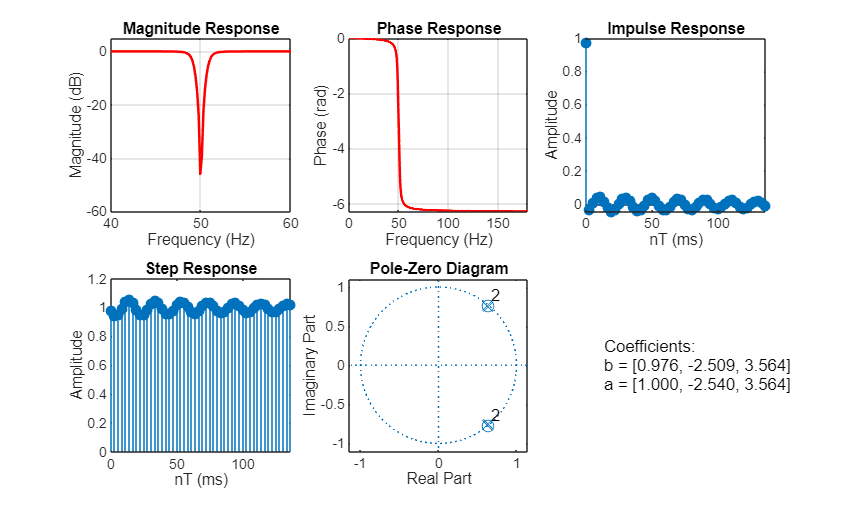

%Filter 2: Notch IIR Butterworth
notch_f0 = 50; 
notch_BW = 2; 
notch_freqs = [notch_f0 - notch_BW/2, notch_f0 + notch_BW/2] / nyquist;
[notch_b, notch_a] = butter(2, notch_freqs, 'stop');

figure('Name', 'Notch Filter (50 Hz)', 'Position', [100 100 1000 600]);
[H_n, w_n] = freqz(notch_b, notch_a, 1024, fs);
subplot(2,3,1); plot(w_n, 20*log10(abs(H_n)), 'r', 'LineWidth', 1.5); grid on;
title('Magnitude Response'); xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)'); xlim([40 60]); ylim([-60 5]);
subplot(2,3,2); plot(w_n, unwrap(angle(H_n)), 'r', 'LineWidth', 1.5); grid on;
title('Phase Response'); xlabel('Frequency (Hz)'); ylabel('Phase (rad)'); xlim([0 nyquist]);
subplot(2,3,3); impz(notch_b, notch_a, 50, fs); title('Impulse Response');
subplot(2,3,4); stepz(notch_b, notch_a, 50, fs); title('Step Response');
subplot(2,3,5); zplane(notch_b, notch_a); title('Pole-Zero Diagram');
subplot(2,3,6); text(0.1, 0.5, {'Coefficients:', sprintf('b = [%.3f, %.3f, %.3f]', notch_b(1), notch_b(2), notch_b(3)), sprintf('a = [%.3f, %.3f, %.3f]', notch_a(1), notch_a(2), notch_a(3))}); axis off;

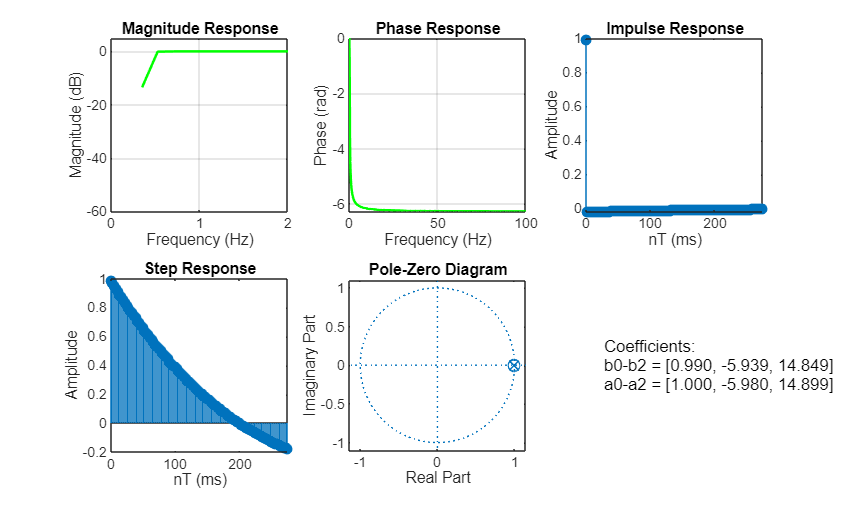

%Filter 3: High-pass Chebyshev Type II
hp_fstop = 0.3; 
[hp_b, hp_a] = cheby2(6, 40, hp_fstop/nyquist, 'high');

figure('Name', 'High-pass Filter (Baseline Wander)', 'Position', [150 150 1000 600]);
[H_hp, w_hp] = freqz(hp_b, hp_a, 1024, fs);
subplot(2,3,1); plot(w_hp, 20*log10(abs(H_hp)), 'g', 'LineWidth', 1.5); grid on;
title('Magnitude Response'); xlabel('Frequency (Hz)'); ylabel('Magnitude (dB)'); xlim([0 2]); ylim([-60 5]);
subplot(2,3,2); plot(w_hp, unwrap(angle(H_hp)), 'g', 'LineWidth', 1.5); grid on;
title('Phase Response'); xlabel('Frequency (Hz)'); ylabel('Phase (rad)'); xlim([0 100]);
subplot(2,3,3); impz(hp_b, hp_a, 100, fs); title('Impulse Response');
subplot(2,3,4); stepz(hp_b, hp_a, 100, fs); title('Step Response');
subplot(2,3,5); zplane(hp_b, hp_a); title('Pole-Zero Diagram');
subplot(2,3,6); text(0.1, 0.5, {'Coefficients:', sprintf('b0-b2 = [%.3f, %.3f, %.3f]', hp_b(1), hp_b(2), hp_b(3)), sprintf('a0-a2 = [%.3f, %.3f, %.3f]', hp_a(1), hp_a(2), hp_a(3))}); axis off;

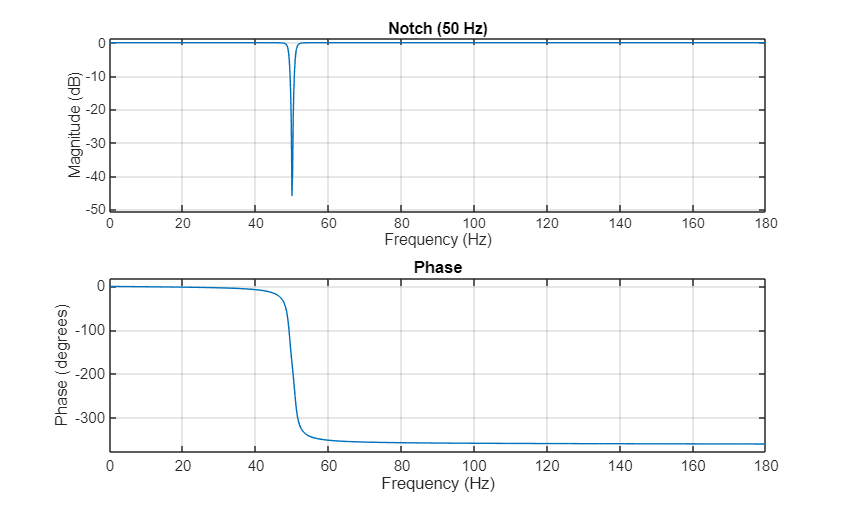

subplot(3,1,2); freqz(notch_b, notch_a, 1024, fs); title('Notch (50 Hz)');

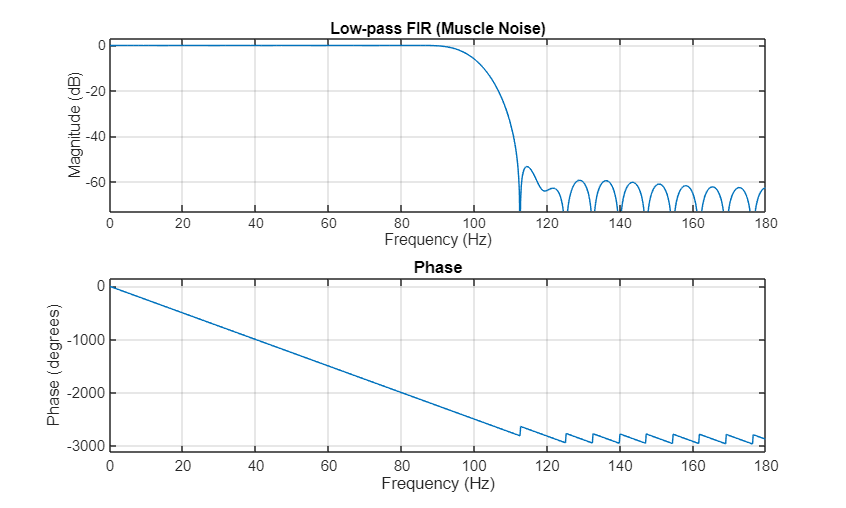

subplot(3,1,3); freqz(lp_fir, 1, 1024, fs); title('Low-pass FIR (Muscle Noise)');

### Loading and Filtering Record 100.

[ecg_100, time_axis] = load_ecg_segment('100', 1000, 10, fs);

ecg_100_hp = filtfilt(hp_b, hp_a, ecg_100);
ecg_100_notch = filtfilt(notch_b, notch_a, ecg_100_hp);
ecg_100_clean = filtfilt(lp_fir, 1, ecg_100_notch);

### Loading and Filtering Record 106.

[ecg_106, ~] = load_ecg_segment('106', 1000, 10, fs);

ecg_106_hp = filtfilt(hp_b, hp_a, ecg_106);
ecg_106_notch = filtfilt(notch_b, notch_a, ecg_106_hp);
ecg_106_clean = filtfilt(lp_fir, 1, ecg_106_notch);

### Time-Domain Comparison.

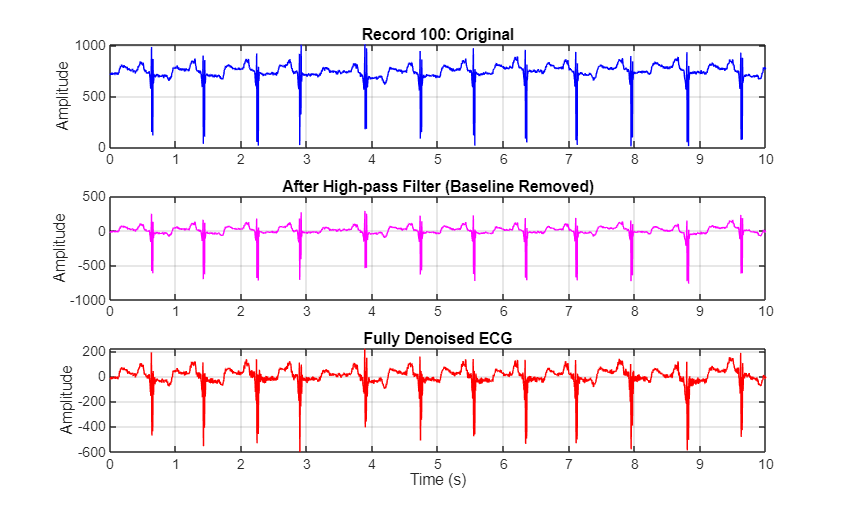

%Record 100
figure('Name', 'Record 100 Denoising Steps', 'Position', [200 200 1000 600]);
subplot(3,1,1); plot(time_axis, ecg_100, 'b'); grid on; title('Record 100: Original'); ylabel('Amplitude'); xlim([0 10]);
subplot(3,1,2); plot(time_axis, ecg_100_hp, 'm'); grid on; title('After High-pass Filter (Baseline Removed)'); ylabel('Amplitude'); xlim([0 10]);
subplot(3,1,3); plot(time_axis, ecg_100_clean, 'r'); grid on; title('Fully Denoised ECG'); xlabel('Time (s)'); ylabel('Amplitude'); xlim([0 10]);

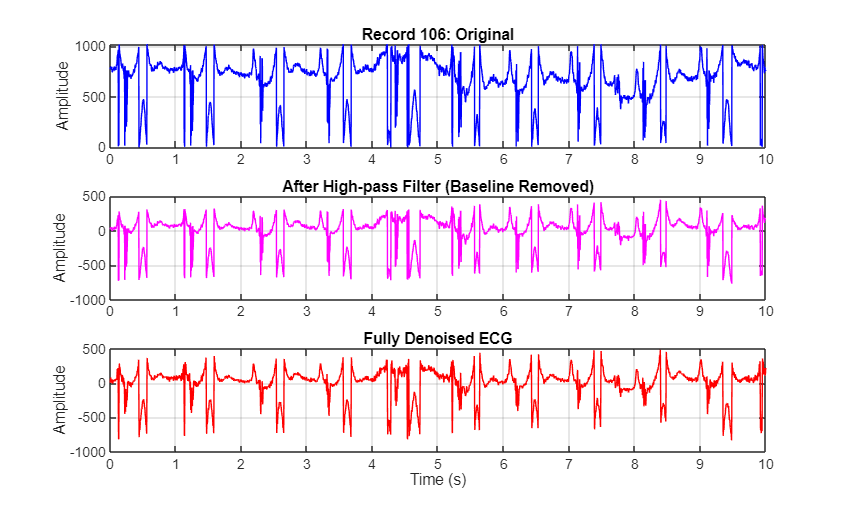

%Record 106
figure('Name', 'Record 106 Denoising Steps', 'Position', [250 250 1000 600]);
subplot(3,1,1); plot(time_axis, ecg_106, 'b'); grid on; title('Record 106: Original'); ylabel('Amplitude'); xlim([0 10]);
subplot(3,1,2); plot(time_axis, ecg_106_hp, 'm'); grid on; title('After High-pass Filter (Baseline Removed)'); ylabel('Amplitude'); xlim([0 10]);
subplot(3,1,3); plot(time_axis, ecg_106_clean, 'r'); grid on; title('Fully Denoised ECG'); xlabel('Time (s)'); ylabel('Amplitude'); xlim([0 10]);

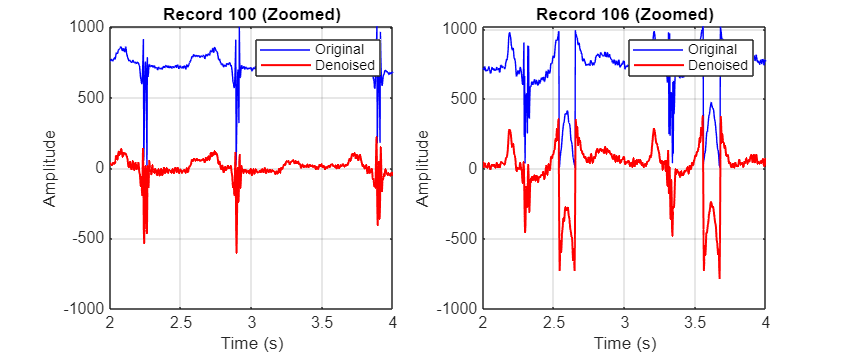

%Zoomed windows
figure('Name', 'Zoomed Comparison (2 seconds)', 'Position', [300 300 1200 500]);
subplot(1,2,1);
plot(time_axis, ecg_100, 'b', 'DisplayName', 'Original'); hold on;
plot(time_axis, ecg_100_clean, 'r', 'LineWidth', 1.2, 'DisplayName', 'Denoised');
grid on; xlabel('Time (s)'); ylabel('Amplitude'); title('Record 100 (Zoomed)'); xlim([2 4]); legend;

subplot(1,2,2);
plot(time_axis, ecg_106, 'b', 'DisplayName', 'Original'); hold on;
plot(time_axis, ecg_106_clean, 'r', 'LineWidth', 1.2, 'DisplayName', 'Denoised');
grid on; xlabel('Time (s)'); ylabel('Amplitude'); title('Record 106 (Zoomed)'); xlim([2 4]); legend;

### Frequency-Domain Analysis.

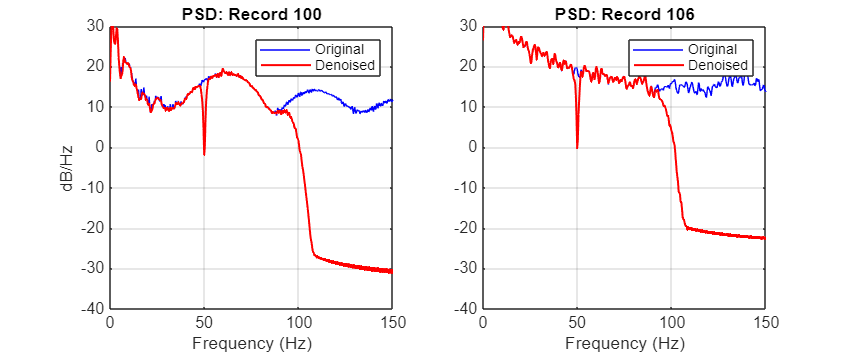

%Welch method to view frequency contents
win = hamming(512); nov = 256; nfft = 1024;
[pxx_100_orig, f] = pwelch(ecg_100, win, nov, nfft, fs);
[pxx_100_den, ~]  = pwelch(ecg_100_clean, win, nov, nfft, fs);
[pxx_106_orig, ~] = pwelch(ecg_106, win, nov, nfft, fs);
[pxx_106_den, ~]  = pwelch(ecg_106_clean, win, nov, nfft, fs);

figure('Name', 'Power Spectral Density', 'Position', [350 350 1200 500]);
subplot(1,2,1);
plot(f, 10*log10(pxx_100_orig), 'b'); hold on; plot(f, 10*log10(pxx_100_den), 'r', 'LineWidth', 1.2);
grid on; xlim([0 150]); ylim([-40 30]); title('PSD: Record 100'); xlabel('Frequency (Hz)'); ylabel('dB/Hz'); legend('Original', 'Denoised');

subplot(1,2,2);
plot(f, 10*log10(pxx_106_orig), 'b'); hold on; plot(f, 10*log10(pxx_106_den), 'r', 'LineWidth', 1.2);
grid on; xlim([0 150]); ylim([-40 30]); title('PSD: Record 106'); xlabel('Frequency (Hz)'); legend('Original', 'Denoised');

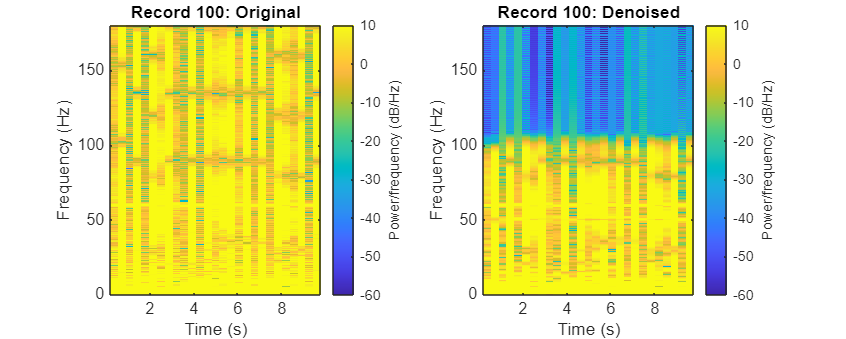

% Spectrograms
figure('Name', 'Spectrograms Record 100', 'Position', [400 400 1000 400]);
subplot(1,2,1); spectrogram(ecg_100, hamming(256), 128, 512, fs, 'yaxis'); title('Record 100: Original'); clim([-60 10]);
subplot(1,2,2); spectrogram(ecg_100_clean, hamming(256), 128, 512, fs, 'yaxis'); title('Record 100: Denoised'); clim([-60 10]);

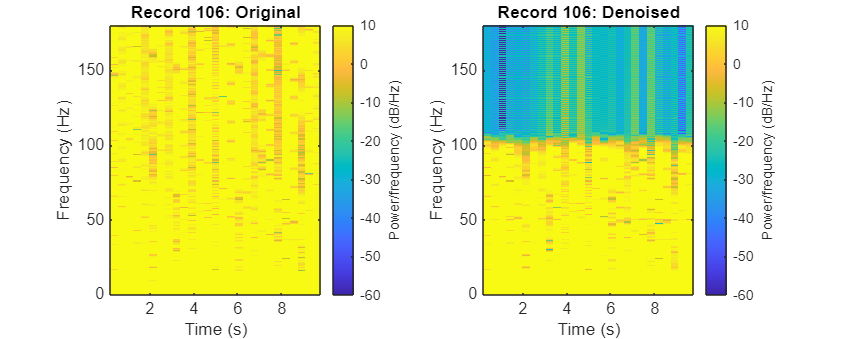


figure('Name', 'Spectrograms Record 106', 'Position', [450 450 1000 400]);
subplot(1,2,1); spectrogram(ecg_106, hamming(256), 128, 512, fs, 'yaxis'); title('Record 106: Original'); clim([-60 10]);
subplot(1,2,2); spectrogram(ecg_106_clean, hamming(256), 128, 512, fs, 'yaxis'); title('Record 106: Denoised'); clim([-60 10]);

### SNR Calculations.

calc_snr = @(orig, clean) 10 * log10(mean(clean.^2) / mean((orig - clean).^2));

snr_100 = calc_snr(ecg_100, ecg_100_clean);
snr_106 = calc_snr(ecg_106, ecg_106_clean);

disp('Denoising Results (Estimated SNR After Filtering)');

Denoising Results (Estimated SNR After Filtering)


disp(['Record 100 (Normal) SNR:   ', num2str(snr_100), ' dB']);

Record 100 (Normal) SNR:   -19.8627 dB


disp(['Record 106 (Abnormal) SNR: ', num2str(snr_106), ' dB']);

Record 106 (Abnormal) SNR: -10.1723 dB
